Data testing with initial data collected on longboard indoors

[Push_MotionData]=ParseMatlabApp('initial_indoor_data/push_indoor.mat')

Push_MotionData = struct with fields:
            Accel: [313×3 double]
      Orientation: [313×3 double]
           AngVel: [314×3 double]
         Position: [31×6 double]
          t_Accel: [313×1 double]
    t_Orientation: [313×1 double]
         t_AngVel: [314×1 double]
       t_Position: [31×1 double]
       accel_rate: 10.0289
      orient_rate: 10.0289
      AngVel_rate: 10.0292
      Positi_rate: 1.0174


t = Push_MotionData.t_Accel; 
accel = Push_MotionData.Accel;
ax = accel(:,1);
ay = accel(:,2);
az = accel(:,3);
Fs = 10

Fs = 10

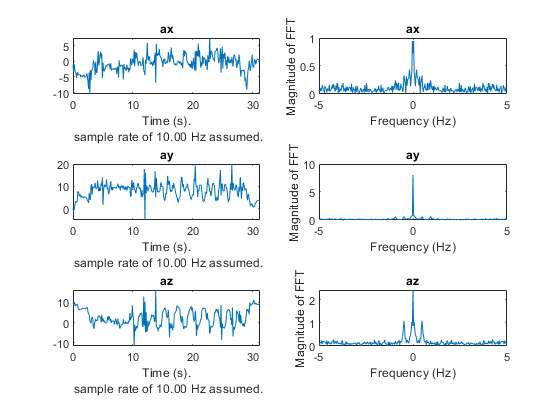

N = size(accel);
N = N(1);
f = linspace(-Fs/2 , Fs/2 - Fs/N, N) + Fs/(2*N)*mod(N,2);

subplot(3,2,1)
make_time_plot(ax, Fs, 'ax')
subplot(3,2,2)
make_freq_plot(ax, Fs, 'ax')

subplot(3,2,3)
make_time_plot(ay, Fs, 'ay')
subplot(3,2,4)
make_freq_plot(ay, Fs, 'ay')

subplot(3,2,5)
make_time_plot(az, Fs, 'az')
subplot(3,2,6)
make_freq_plot(az, Fs, 'az')

## Trying out different filters

Try to use 3 pt moving fitler to smooth out noise. Used az (acceleration in z axis bc that was where the major peaks were)

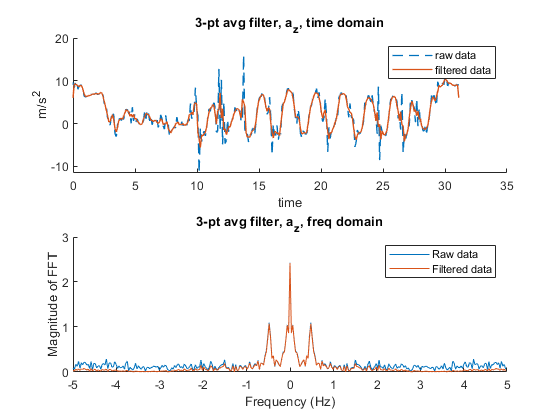

% Filter az with 3 pt moving avg
filt_az = movingavg2(az);

% Plot in time domain
figure
subplot(2, 1, 1)
hold on
h= plot(t, az,  '--') ;
set(h,'LineWidth', 1);
h = plot(t, filt_az);
set(h,'LineWidth', 1);
xlabel("time");
ylabel("m/s^2");
legend("raw data", "filtered data")
title("3-pt avg filter, a_z, time domain")
hold off

% Plot in freq domain
subplot(2, 1, 2)
hold on
make_freq_plot(az, Fs, "filtered push az")
make_freq_plot(filt_az, Fs, "3-pt avg filter, a_z, freq domain")
legend("Raw data", "Filtered data");
hold off

Tried to use highpass filter to get rid of gravity - didn't work. I don't think we should use this filter bc it gets rid of the low frequencies we need. 

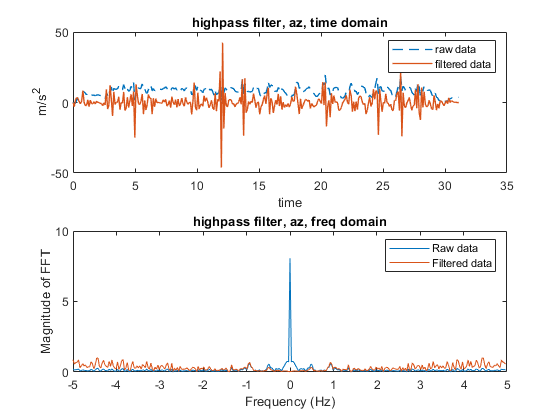

filt_ay = highpass(ay);

% Plot in time domain
figure
subplot(2, 1, 1)

h= plot(t, ay,  '--') ;
set(h,'LineWidth', 1);
hold on;
h = plot(t, filt_ay);
set(h,'LineWidth', 1);
hold off
xlabel("time");
ylabel("m/s^2");
legend("raw data", "filtered data")
title("highpass filter, az, time domain")

% Plot in freq domain
subplot(2, 1, 2)

make_freq_plot(ay, Fs, "filtered push az")
hold on
make_freq_plot(filt_ay, Fs, "highpass filter, az, freq domain")
legend("Raw data", "Filtered data");
hold off

Try to reduce huge peak bc of gravity by reducing amplitude of frequencies between -0.2 Hz and 0.2 Hz. We should automate this for all the data we collect. 

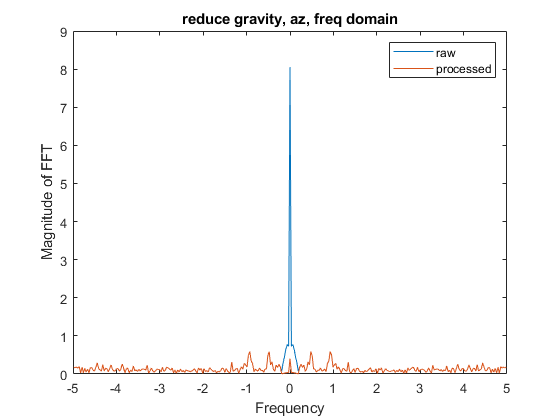


% Delete entry at freq = 0 to get rid of gravity
fft_ay = fftshift(fft(ay));
figure
plot(f, 1/length(ay)*abs(fft_ay))
hold on

% process data in this range
low_range = -0.2;
high_range = 0.2;
for k = 1:size(fft_ay)
    if (f(k) >= low_range && f(k) <= high_range)
        % Make amplitude smaller
        fft_ay(k) = fft_ay(k)*0.05;
    end
end
plot(f, 1/length(ay)*abs(fft_ay))
xlabel("Frequency")
ylabel("Magnitude of FFT")
title("reduce gravity, az, freq domain")
legend("raw", "processed")
hold off

Test reduce gravity function

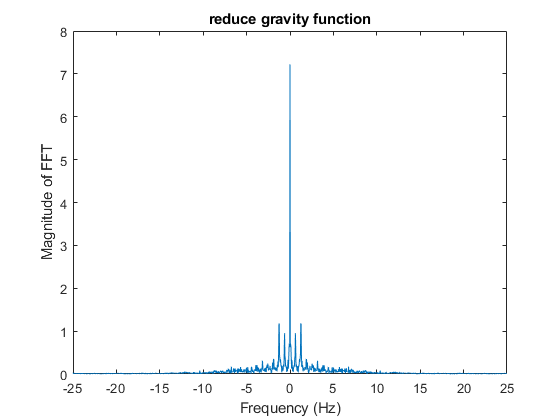

make_freq_plot(ay, Fs, "reduce gravity function");
hold on

filt_ay = reduce_gravity(ay, f, 0.2);

filt_ay =     0.0459
    0.2917
    0.3972
    0.5587
    0.7017
    0.5974
    0.1244
   -0.2479
   -0.4427
   -1.1162


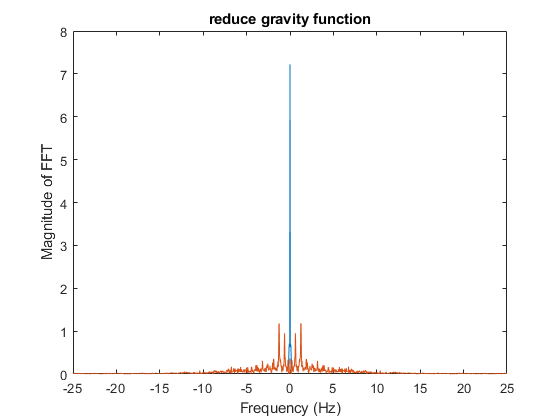

make_freq_plot(filt_ay, Fs, "reduce gravity function")
hold off

function y = movingavg(x)
    y = movmean(x,3, 'Endpoints', 'discard');
    % Add end elements
    y = [(x(1)+x(2))/3, y'];
    y(end+1) = (x(end-1) + x(end))/3;
end

function y = movingavg2(a_x)
    y = [a_x(1) + a_x(2); a_x(1:end-2) + a_x(2:end-1) + a_x(3:end); a_x(end-1) + a_x(end)]/3;
end

function y = highpass(x)
    y = zeros(size(x));
    for i = 2: size(x)
        y(i) = (x(i)-x(i-1))/0.5;
        
    end
end